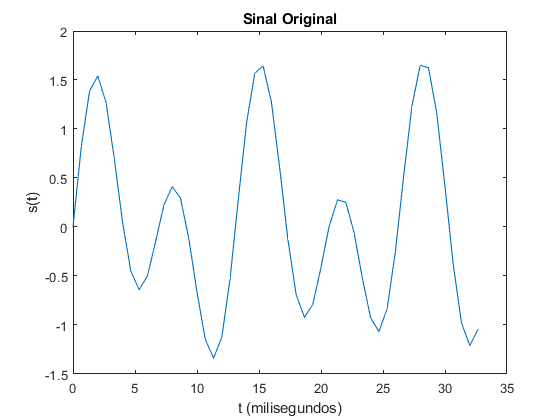

clear
close all;

fs = 1500;
T = 1/fs;
tempoSinal = 1;
t = 0:T:tempoSinal; % (0:tempoSinal-1)*T

sinal = 0.7*sin(2*pi*80*t) + sin(2*pi*150*t);
plot(1000*t(1:50),sinal(1:50));
title('Sinal Original');
xlabel('t (milisegundos)');
ylabel('s(t)');

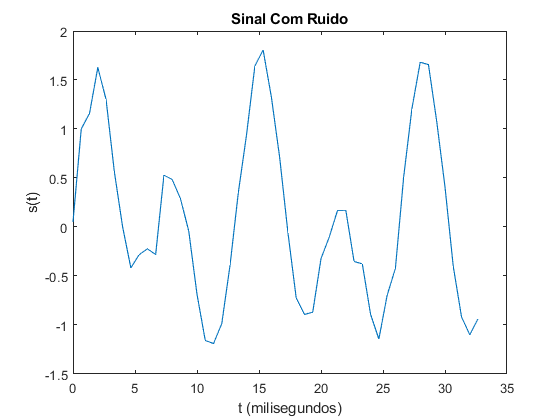


sinalComRuido = sinal + 0.1*randn(size(t));
plot(1000*t(1:50),sinalComRuido(1:50));
title('Sinal Com Ruido');
xlabel('t (milisegundos)');
ylabel('s(t)');

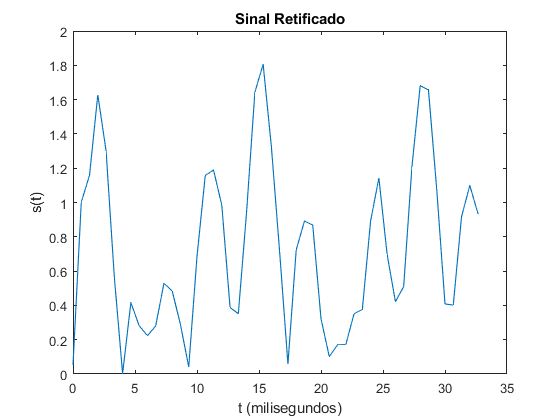


sinalRetificado = abs(sinalComRuido);
plot(1000*t(1:50),sinalRetificado(1:50));
title('Sinal Retificado');
xlabel('t (milisegundos)');
ylabel('s(t)');

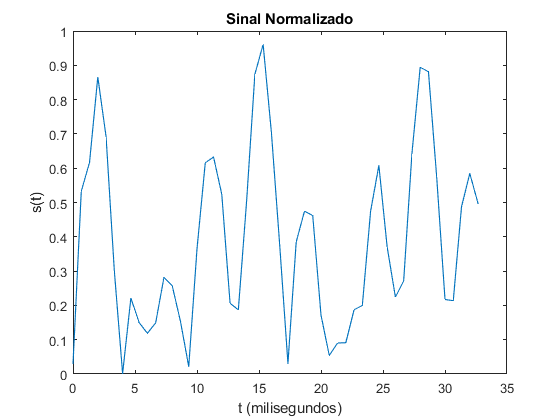


sinalNormalizado = sinalRetificado/max(abs(sinalRetificado));
plot(1000*t(1:50),sinalNormalizado(1:50));
title('Sinal Normalizado');
xlabel('t (milisegundos)');
ylabel('s(t)');




p(1:length(sinal)) = 0;
p(1:1/fs:end) = 1;

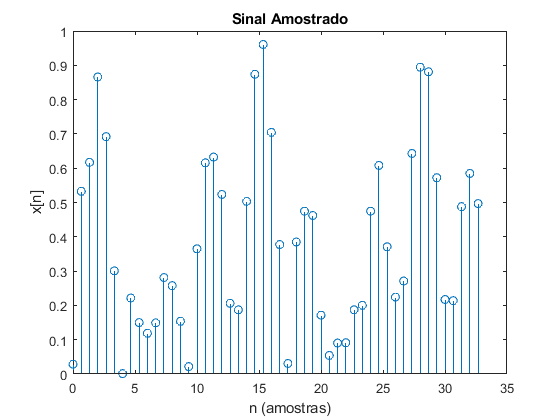

sinalAmostrado = p.*sinalNormalizado;

stem(1000*t(1:50),sinalAmostrado(1:50));
title('Sinal Amostrado')
xlabel('n (amostras)');
ylabel('x[n]');

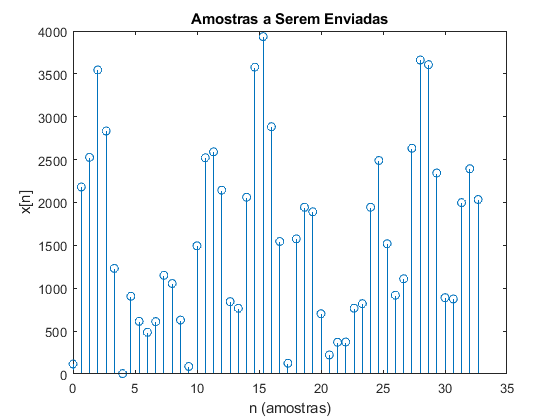


Amostras4096 = round(sinalAmostrado*((2^12)-1));
stem(1000*t(1:50),Amostras4096(1:50));
title('Amostras a Serem Enviadas');
xlabel('n (amostras)');
ylabel('x[n]');

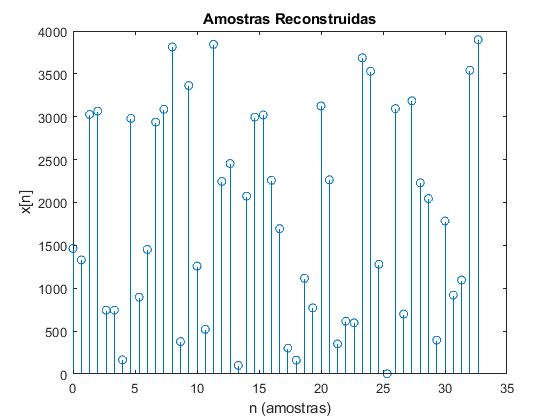


matrizBits12xn = converte2binario(Amostras4096);
%sinalBinario(:,1:10)

matrizMensangens = mudaTamanho(matrizBits12xn, 4);
%sequenciaNibbles(:,1:30)
[PalavrasCodigo, G, H] = codificacao(matrizMensangens);
%listaPalavrasCodigo(:,1:30)
sequenciaBinariaEnviada = mudaTamanho(PalavrasCodigo, 1);

% Pe = 0.1
sequenciaBinariaRecebida = BSC(sequenciaBinariaEnviada);

PalavrasCodigoRecebidas = mudaTamanho(sequenciaBinariaRecebida, 7);
[qtd_erros, mensagensDecodificadas] = decodificacao(PalavrasCodigoRecebidas, H);
%mensagensDecodificadas(:,1:30)

sinalBinarioRecebido = mudaTamanho(mensagensDecodificadas, 12);
%sinalBinarioRecebido(:,1:30)

sinalReconstruido = converte2decimal(sinalBinarioRecebido);
stem(1000*t(1:50),sinalReconstruido(1:50));
title('Amostras Reconstruidas');
xlabel('n (amostras)');
ylabel('x[n]');